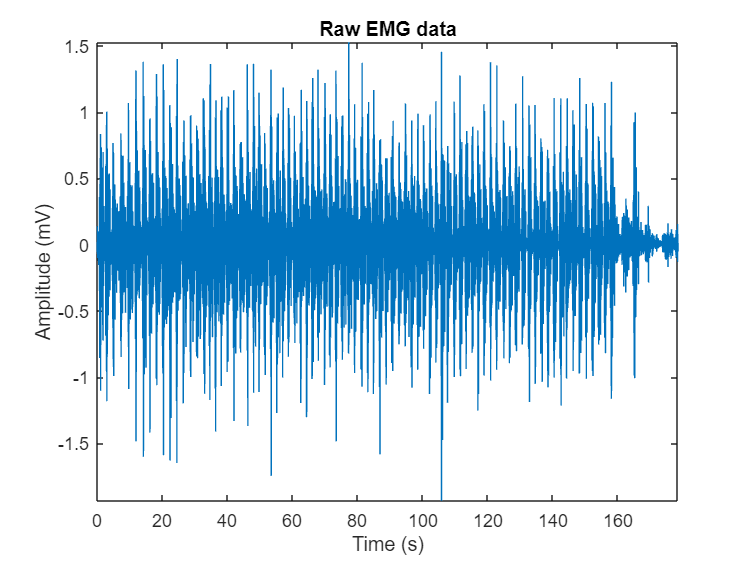

% load the file rawEMG_data.mat
load(['C:\Users\adi03\Downloads\BME235 Lab Data\simone_cold.mat'])
time = b1(:, 1);
emg = b1(:, 2);
% plot the raw EMG recording from the biceps
figure,
plot(time, emg)
xlabel('Time (s)')
ylabel('Amplitude (mV)')
axis tight
title('Raw EMG data')

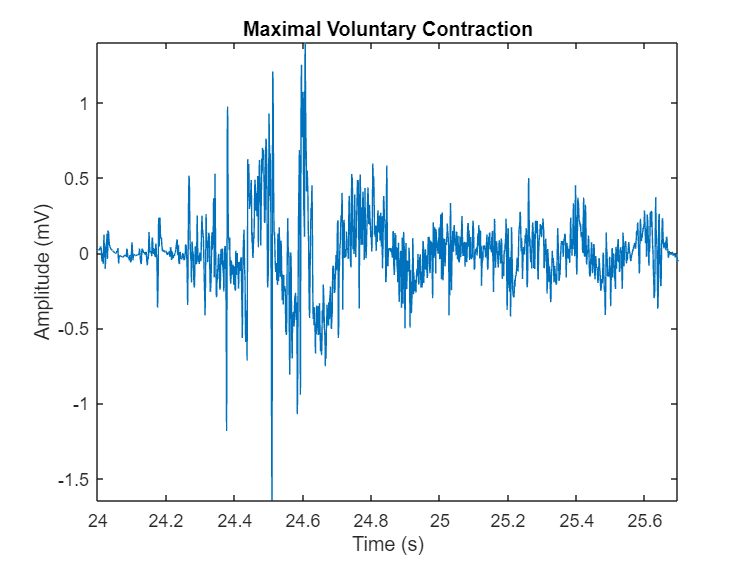

% this script extract only the EMG between 6-10 seconds
fs = 1000;
t1 = 24;
t2 = 25.7;
mvc = emg(fs*t1:fs*t2);
mvc_t = time(fs*t1:fs*t2);



% plot the MVC 
figure,
plot(mvc_t, mvc)
xlabel('Time (s)')
ylabel('Amplitude (mV)')
axis tight
title('Maximal Voluntary Contraction')

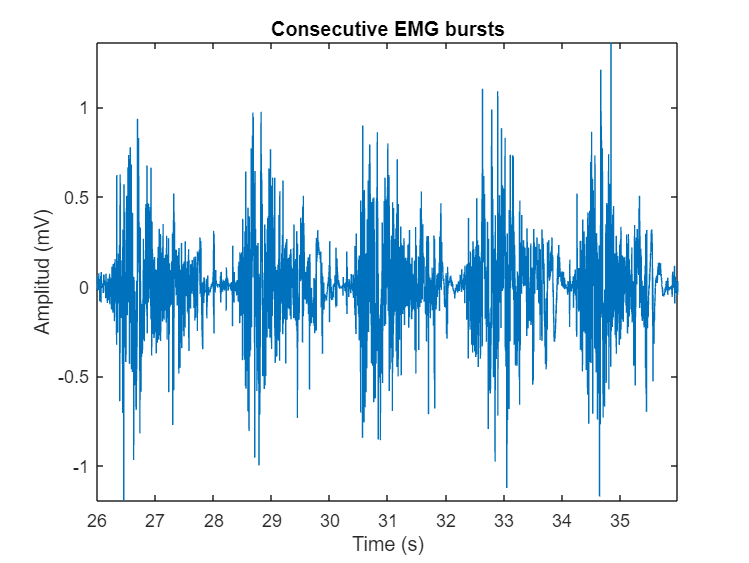

t1 = 26;
t2 = 36;
emg_brst = emg(fs*t1:fs*t2);
time_seg = time(fs*t1:fs*t2); 
% plot the consecutive contractions
figure,
plot(time_seg, emg_brst)
xlabel('Time (s)')
ylabel('Amplitud (mV)')
title('Consecutive EMG bursts')
axis tight

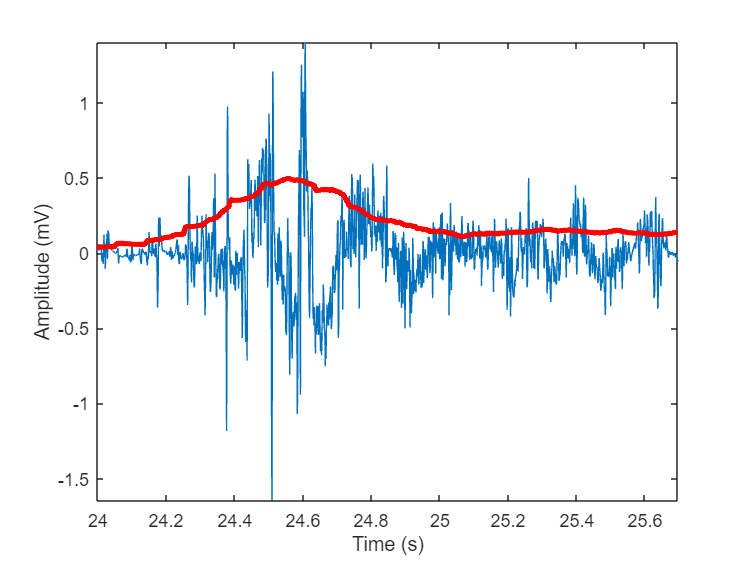

win = 250; 
rms_mvc = sqrt(movmean(mvc .^2, win)); % moving rms
rms_emg = sqrt(movmean(emg_brst .^2, win)); % moving rms
% the bold red line represents the RMS of the EMG signal 
% in both figures
figure,
plot(mvc_t, mvc)
hold on
plot(mvc_t, rms_mvc,'r','Linewidth',3)
xlabel('Time (s)')
ylabel('Amplitude (mV)')
axis tight

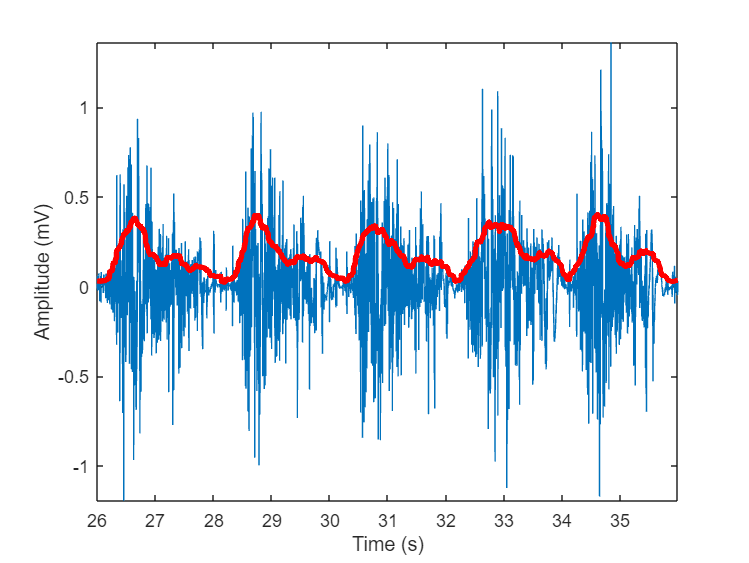

figure,
plot(time_seg, emg_brst)
hold on
plot(time_seg, rms_emg,'r','Linewidth',3)   

xlabel('Time (s)')
ylabel('Amplitude (mV)')
axis tight